# Seeding the random number generation


rng(1)
N=1000; % Length of the data
txname='tx.dat';

## Generate complex white noise pulses TX Data

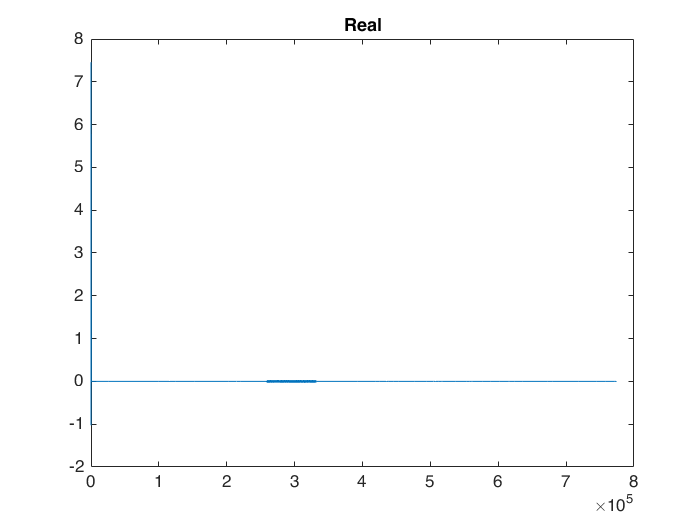

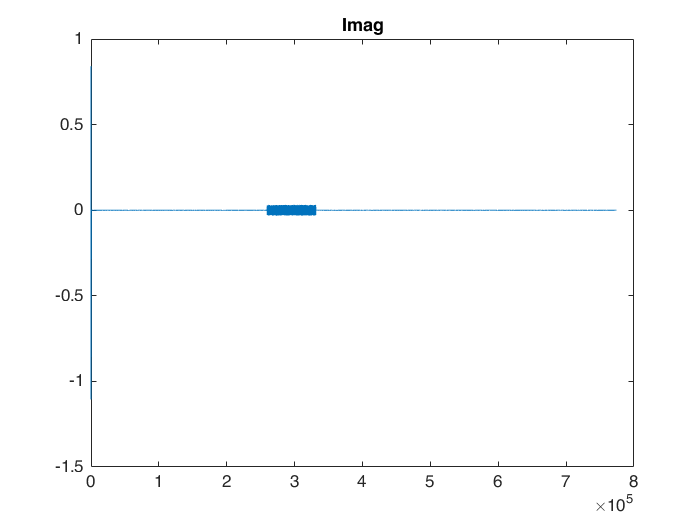

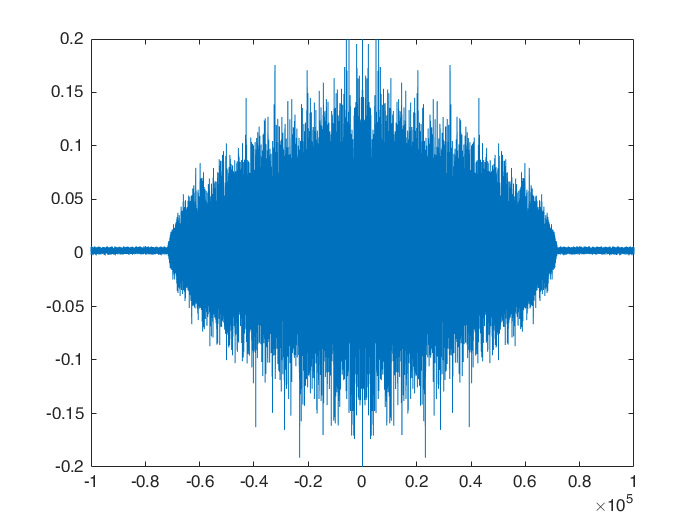

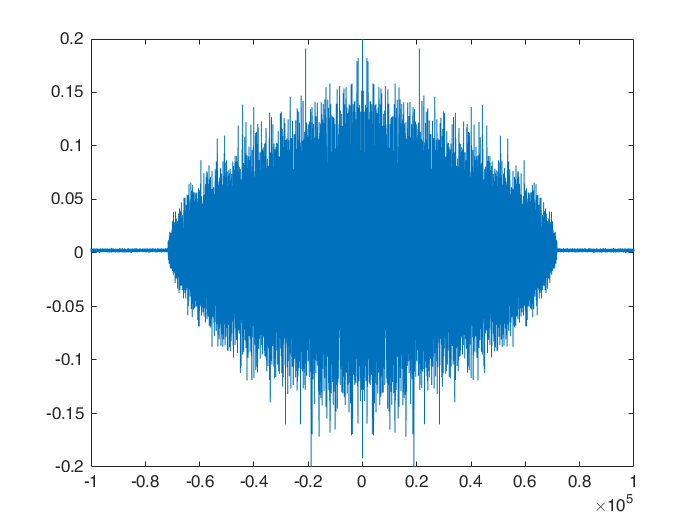

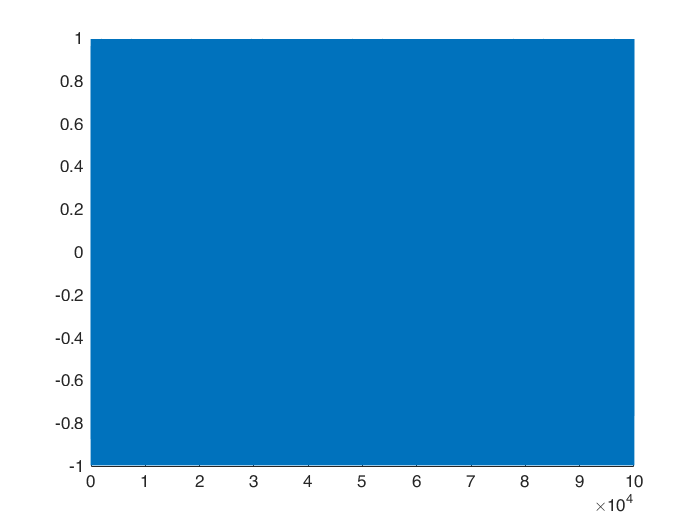

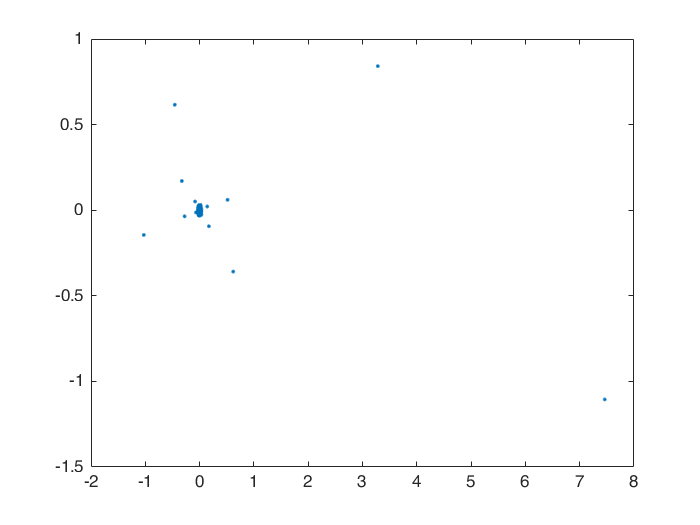


dat=sign(randn(N,1))+j*sign(randn(N,1)); 

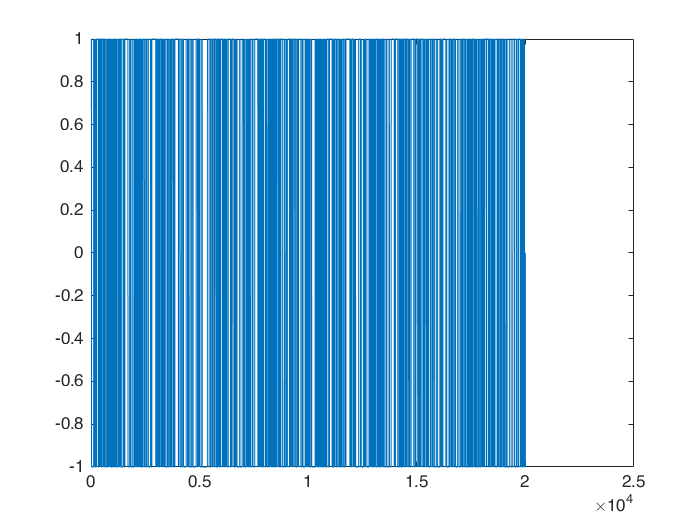

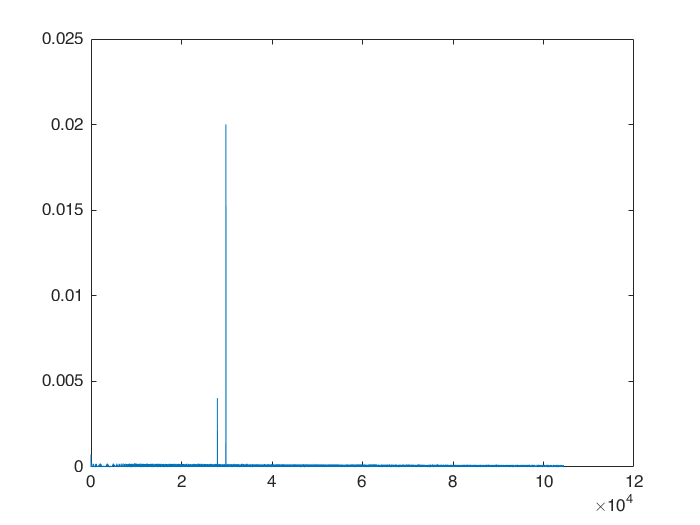

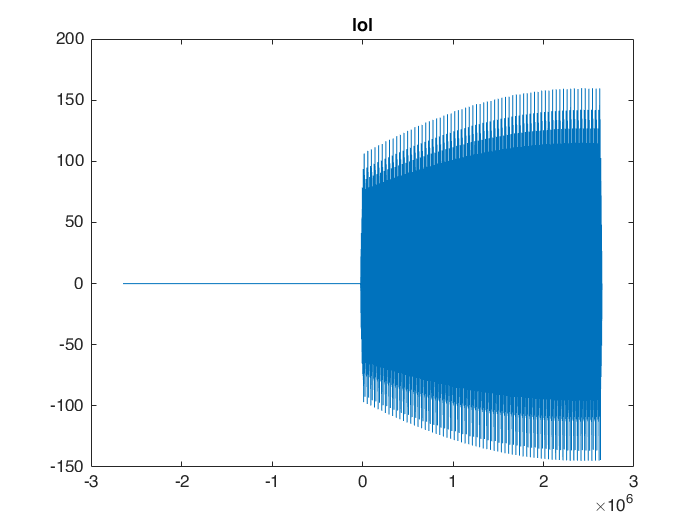

Invalid use of operator.

err_rate = 0.4370

x_us=upsample(dat,20);
pulse=ones(20,1);

x=conv(x_us,pulse);

write_usrp_data_file(x,txname)

## Generate a cosine

x=1:N;
cos_Dat=cos(2*pi/25*x);
write_usrp_data_file(cos_Dat)
plot(cos_Dat)

write_usrp_data_file(x,txname)